# WPI HPRC Flight Playback

Author: Daniel Pearson

Version: 2/7/2023

clear variables; close all; clc;

## Earth Constants

a_earth = 6378137.0;       % [m] Semi-major axis of Earth
% b_earth = 6356752.3142;    % [m] Semi-Minor axis of Earth
e_earth = 0.0818191908426; % Eccentricity of Earth
b_earth = a_earth * sqrt(1 - e_earth^2);
r_earth = 6378137;         % [m] Radius of Earth
omega_earth = 7.2921159e-5; % Earth's rotation rate in radians per second

## Load Data

data = readtable('DataLog.csv');

% time = strsplit(data.Time,":");
% date = [2024, 2, 8, time]

time = data.Time(data.LON_DEG ~= 0);

for i = 1:length(data.Time)
    time = data.Time(i);
    utc(i,:) = round([2024, 2, 8, hours(time), mod(minutes(time), 60), mod(seconds(time),60)]);
end

latNonZero = deg2rad(data.LAT_DEG(data.LAT_DEG ~= 0));
lonNonZero = deg2rad(data.LON_DEG(data.LON_DEG ~= 0));
altNonZero = deg2rad(data.ALT_MSL(data.LON_DEG ~= 0));


## Convert Position to ECEF

r_adj = r_earth + data.ALT_MSL;
N_earth = a_earth ./ sqrt(1 - e_earth.^2 * sin(latNonZero).^2);

X = (N_earth + altNonZero) .* cos(latNonZero) .* cos(lonNonZero);
Y = (N_earth + altNonZero) .* cos(latNonZero) .* sin(lonNonZero);
Z = ((b_earth^2 / a_earth^2)*N_earth + altNonZero) .* sin(latNonZero);

r_ecef = [X,Y,Z];

julianDate = mjuliandate(utc);
pm = polarMotion(julianDate, 'action', 'none')*(180/pi);

for i = 1:length(r_ecef)
    eci = ecef2eci(utc(i,:), r_ecef(i,:), 'pm', pm(i,:));

    eciStore(i,:) = eci;
end

% eci = ecef2eci(utc, r_ecef, 'pm', pm);

## Plot Lat and Long

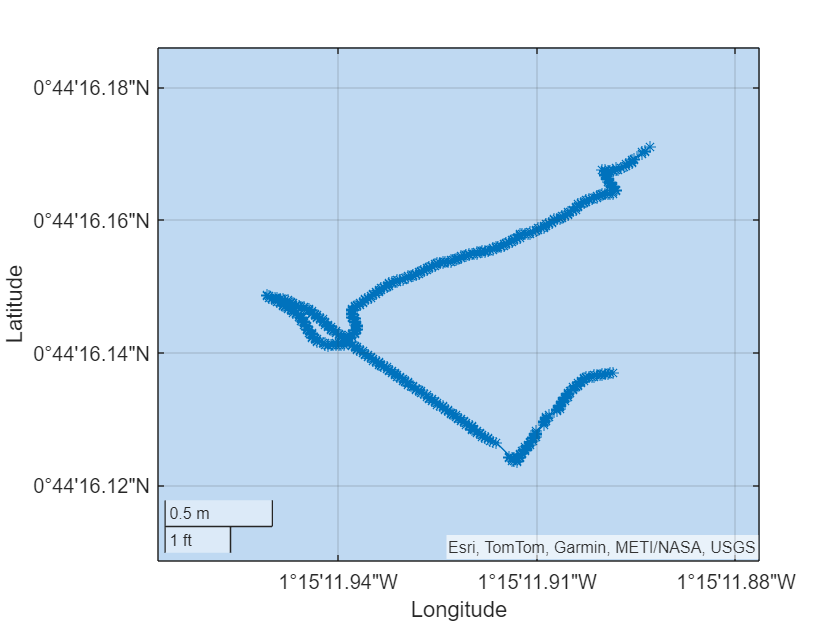

geoplot(latNonZero, lonNonZero, '-*')
geobasemap streets